#  Chapter 6 - State Space Design of Control Systems 

##  Section 3 - Pole Placement / Pole Placement Technique

clear all; clc; 

**Notes:**

Assume all state variables are measurable and are available for feedback. If the system is completely state controllable, then poles of the closed-loop system may be placed at any desired locations by means of state feedback through an appropriate state feedback gain matrix. By choosing the correct gain, you can force system to have closed-loop poles at any desired location. 

For this section, we are only looking at Single-Input-Single-Output systems. With vector quantities = state feedback gain is not unique. 

DESIGN BY POLE PLACEMENT: In the conventional approach, we design a controller to the dominant closed-loop poles have a desired damping ratio, zeta, and an undamped natural frequency, wn. This method only specifies dominant poles.....assume nondominant closed loop poles are negligible. 

The pole-placement approach specifies all closed-loop poles. The system is required to be completely state controllable, so that the closed-loop poles are places at arbitrarily chose locations? 

Looking at the block diagram below, we assume that all state variables are availiable for feedback and that u (state feedback gain matrix: u = -Kx) is unconstrained. This closed-loop system has no input, and the objective is to maintain a zero output even though there are disturbances present. This is knowns as a *Regulator System*. This system can be stable if the appropriate K, A, and B matrices are chosen properly. The eigenvalues of the matrix A-BX are called the *regulator poles.*...if they are placed in the LHP the system will approach 0 (stable). Selecting these poles is knows as the *pole-placement problem.* 

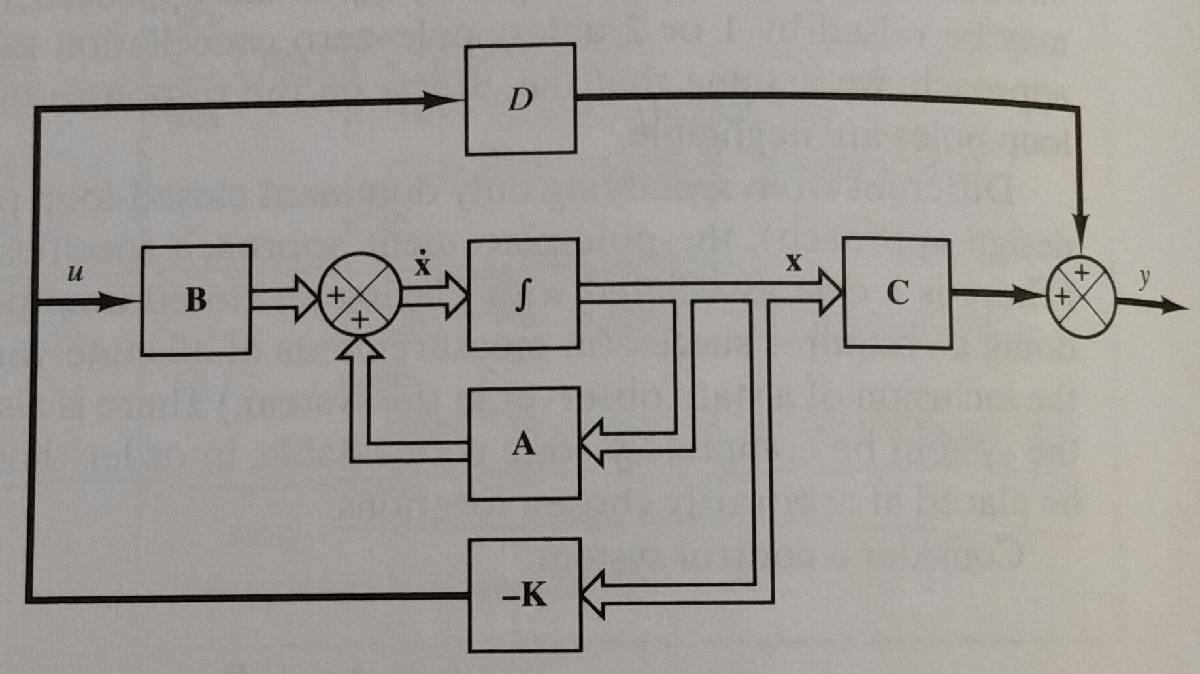

Deterimining the matrix, K, by direct substitution method (pg 315)

Determining the matrix, K, by Ackermann's formula (pg 315- 317)

- Lots of derivations/ matrix math....

Regulator systems and control systems (pg 317)

- Systems that include controllers can be divided into two parts: (1) regulator systems, where the reference input is constant and (2) control systems, where the reference input is time varying. 

Chosing the locations of desired closed-loop poles (pg 317 - 318)

- Step 1 of pole-placement design is to choose locations of desired closed-loop poles

- A. Choose based on root-locus design....placing dominant pair of closed loop poles and then other poles that are far far to the left of the dominant closed-loop poles

- If we place the dominant closed-loop poles far from the imaginary axis, the system response will be very fast and the system will become very nonlinear/unstable. 

- B. Choose based on Quadratic Optimal control approach, which determines desired poles based on the response and amount of control energy required. High-speed response = large amount of control energy. 

## 6-3 Determine the state feedback gain matrix, K

Given a regulator system and state feedback control. Choose the desired closed-loop poles at specified locations. 

% Given : 
A = [0 1 0; 0 0 1; -1, -5, -6];
B = [0; 0; 1];

Step 1 : Check controllability of the system based on A and B matrices. If the system is completely state controllable, then arbitrary pole placement is possible. 

Step 2 : Define the desired state feedback gain matrix, $K=\text{ }\left\lbrack k_1 \text{ }{\text{ }\text{ }\text{ }k}_2 {\text{ }\text{ }\text{ }k}_3 \right\rbrack$ and equating $\left|sI−A+BK\right|$ with the desired characteristic equation. OR use Ackermann's formula to determine K. 